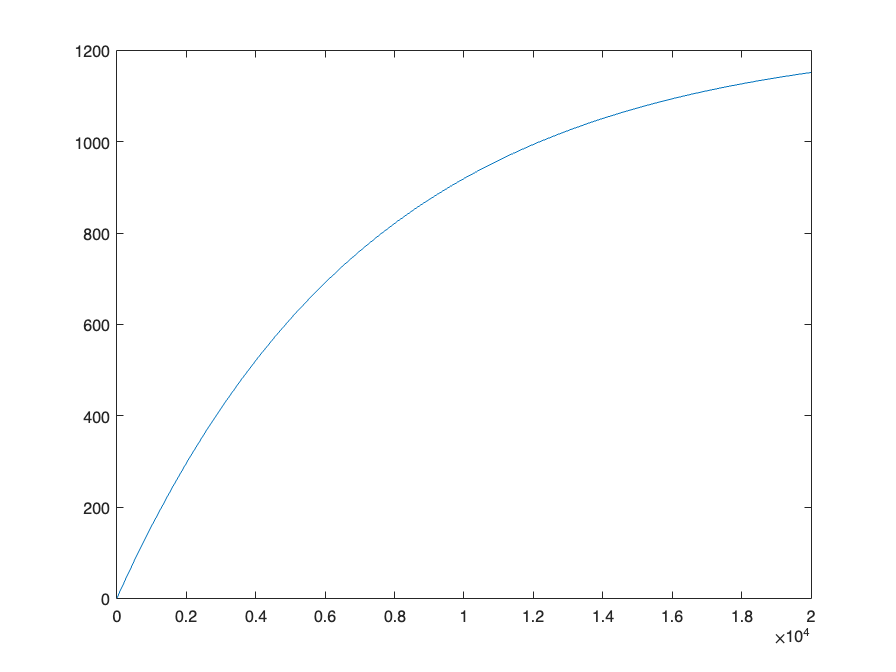

clear

% Constant Parameters
k_s = 0.3; % W/(m*K), thermal conductivity of silicone (estimate)
L_s = .0015; % m, silicone thickness
% TODO: find approximate h
h_s = 40; % W/(m^2*K), heat transfer coefficient of silicone
A_s =.00173104; % m^2, external surface area of silicone
A_sb =.00118045; % m^2, contact area of block and silicone
c_b = 389; % J/(kg*K), specific heat of block
m_b =.03023; % kg, mass of block (including nozzle)
m_s = .00255; % kg, mass of silicone  
T_air = 296.25; % K, ambient air temperature
T_r = 200; % K, goal temperature
Q_in = 50; % W, input power from heating cartridge

% PID parameters
% P = 23.713;
% i = 1.34; 
% D = 104.932;


R_total = L_s / (k_s * A_sb) + 1 / (h_s * A_s);

dTdt = @(t, T_c) 1/c_b * ((T_air - T_c)/R_total + Q_in);
% dTdt = @(T_c) 1/c_b * ((T_c - T_r)/R_total + P*(T_r - T_c) + D(dT/dt) + f) % PID eqn.


tspan = [0 20000];
y0 = 0;
[t,y] = ode45(dTdt, tspan, y0);

plot(t,y)